**Algorithm for getting Ackerman error**

The purpose of this algorithm is to get the average Ackerman error of a steering system given its dimensions and steering knuckle angle. 

The steering mechanism that will be used is rack-pinion.

A commercial vehicle rack will be chosen based on our needs. Some of the current options are: 

1) 

% Dimensions (cm)
k_arm = 10;     % arm connected to knuckle 
tie_rod = 21;   % intermediate arm
rack = 35;
track = 80;    % wheelbase width
d = 18.72;     % Distance between rack & front chassis
tire = 15; 

% Angles
gamma_l = 27; gamma_r = 27; % Angles between tie rod and rack projection
alpha = 22;  % Angle between tire and knuckle arm (fixed angle)
steer = -20;   % Steering angle
beta = 90 - alpha - steer;  % whole angle between tire and front chassis

% Cosine law for calculating angles to display tire in plot (B = tire/2, C
% = knuckle arm)  ---  tire inside the turn
B = tire / 2;
C = k_arm;
A = sqrt(B^2 + C^2 - 2 * B * C * cos(deg2rad(alpha)))         % Distance from start of knuckle arm to bottom point of tire

A = 4.1440

theta = rad2deg(acos((-B^2 + A^2 + C^2) / (2 * A * C)))

theta = 42.6865

bottom_tire = 180 - (180 - (beta + alpha)) - (alpha + theta)  % Angle of the bottom point of the tire to the horizontal axis

bottom_tire = 45.3135

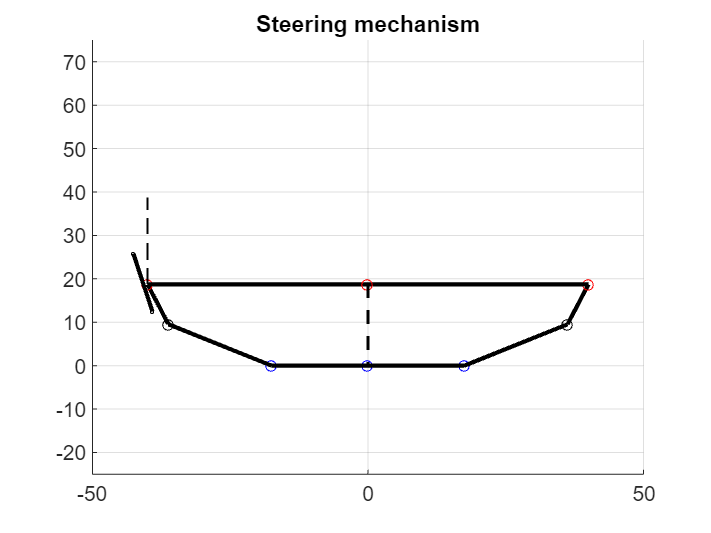


figure(); title('Steering mechanism')
hold on; grid on; xlim([-50 50]); ylim([-25 75]);
plot(0, 0, 'bo', MarkerSize=5);
% Rack
plot(-rack/2, 0, 'bo', MarkerSize=5);
plot(rack/2, 0, 'bo', MarkerSize=5);
plot([-rack/2 rack/2], [0 0], 'k', LineWidth=2); % Unir puntos
% Tie rods
left_tie = [-tie_rod * cos(deg2rad(gamma_l)) - rack/2, tie_rod * sin(deg2rad(gamma_l))];
right_tie = [tie_rod * cos(deg2rad(gamma_r)) + rack/2, tie_rod * sin(deg2rad(gamma_r))];
plot(left_tie(1), left_tie(2), 'ko', MarkerSize=5);
plot(right_tie(1), right_tie(2), 'ko', MarkerSize=5);
plot([left_tie(1), -rack/2], [left_tie(2), 0], 'k', LineWidth=2);
plot([right_tie(1), rack/2], [right_tie(2), 0], 'k', LineWidth=2);
% Knuckle arms
plot([left_tie(1), -track/2], [left_tie(2), d], 'k', LineWidth=2);
plot([right_tie(1), track/2], [right_tie(2), d], 'k', LineWidth=2);
% Track
plot(-track/2, d, 'ro', MarkerSize=5);
plot(track/2, d, 'ro', MarkerSize=5);
plot([-track/2, track/2], [d,d], 'k', LineWidth=2);
% Dist
plot(0, d, 'ro', MarkerSize=5);
plot([0, 0], [d, 0], 'k', LineWidth=1.5, LineStyle='--');
% Inner tire (in turn)
tire_point = [-A * cos(deg2rad(bottom_tire)) + left_tie(1) , A * sin(deg2rad(bottom_tire)) + left_tie(2)];
tire_point_up = [-track/2 - (tire/2) * cos(deg2rad(steer + 90)), d + (tire/2) * sin(deg2rad(90 + steer))];
plot(tire_point(1), tire_point(2), 'ko', MarkerSize=1.5);
plot(tire_point_up(1), tire_point_up(2), 'ko', MarkerSize=1.5);
plot([tire_point(1), tire_point_up(1)], [tire_point(2), tire_point_up(2)], LineWidth=2, Color='k')
% Steering wheel angle
plot([-track/2, -track/2], [d, d+20], LineStyle='--', LineWidth=1, color='k')